## illustrating 1/f and DFT

### Part 1: 1/f and averaging across segments

Start by making a discrete time vector... 

clear
time = 0.001:0.001:1; % one second of discrete time

... and noise segments

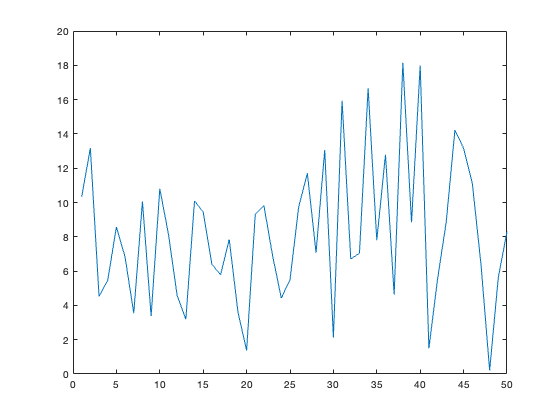

for example = 1:50

    whitesig = rand(1, length(time))-.5; % zero centered white noise
    fftspec = fft(whitesig'); % calculate DFT
    sumspec(example, :) = abs(fftspec); % save it for later
    plot(abs(fftspec (1:50))), pause(.3)

end


figure
plot(mean((sumspec(:, 1:50))))

now we do it again with the cumsum of the white noise, which shoudl result in brownian noise